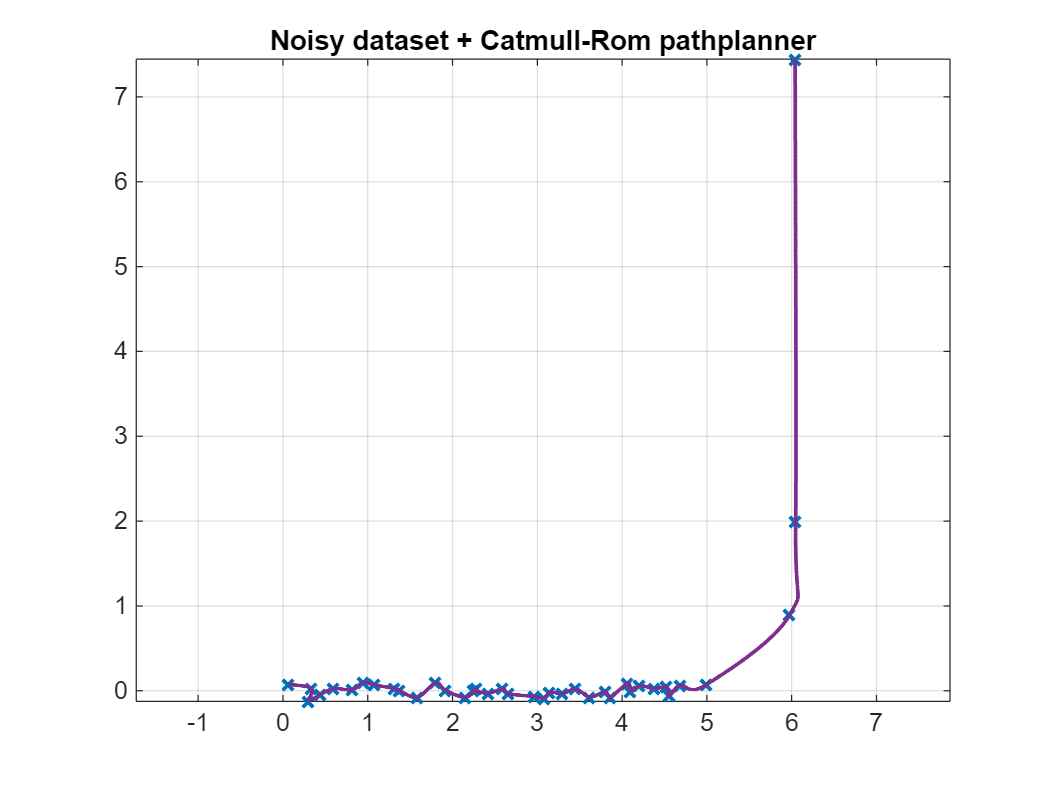

%inputFileName = 'turning_path.csv';
%inputFileName = 'circle_path.csv';
%inputFileName = 'figure8_path_scaled.csv';
inputFileName = 'turning_path_edit.csv';
opts = detectImportOptions(inputFileName);
opts = setvartype(opts, {'x', 'y'}, 'double');
coords = readtable(inputFileName, opts);
coords = table2array(coords);

% coords = ResamplePath(coords, 2);

% figure;
% plot(coords(:,1), coords(:,2), 'x', 'LineWidth', 1.5, 'DisplayName', 'Coordinates');
% grid on;
% axis equal;

noise_level = 0.05; % Adjust this value to control noise magnitude
coords_noisy = coords + noise_level * randn(size(coords));

plot(coords_noisy(:,1), coords_noisy(:,2), 'x', 'LineWidth', 1.5, 'DisplayName', 'Coordinates');
title('Noisy dataset + Catmull-Rom pathplanner');
grid on;
axis equal;
hold on;
[path_x, path_y] = CatmullRomPath(coords_noisy);
plot(path_x, path_y, 'LineWidth', 1.5, 'DisplayName', 'Path');
hold off;

% figure;
% Kappa1 = LineCurvature2D([path_x(1:100:end), path_y(1:100:end)]);
% Kappa1(abs(Kappa1) > 10) = 0;
% plot(Kappa1);
% title('Curvature of noisy dataset + Catmull-Rom pathplanner');
% xlabel('Every 100th point on path');
% ylabel('curvature (1/m)')



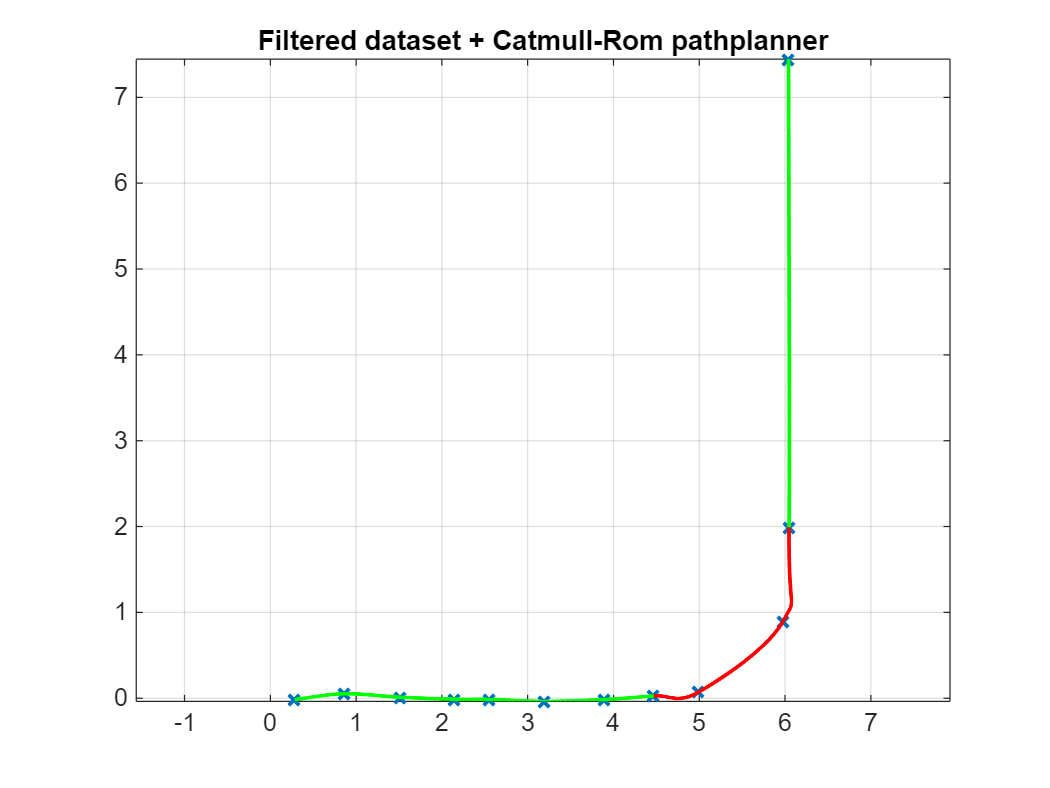

figure;
coords = clusterAverageCoords(coords_noisy, 0.5);
%coords = coords_noisy;
plot(coords(:,1), coords(:,2), 'x', 'LineWidth', 1.5, 'DisplayName', 'Coordinates');
title('Filtered dataset + Catmull-Rom pathplanner');
axis equal;
grid on;
hold on;
[smooth_path_x, smooth_path_y] = CatmullRomPath([coords(:,1), coords(:,2)]);
hold off;

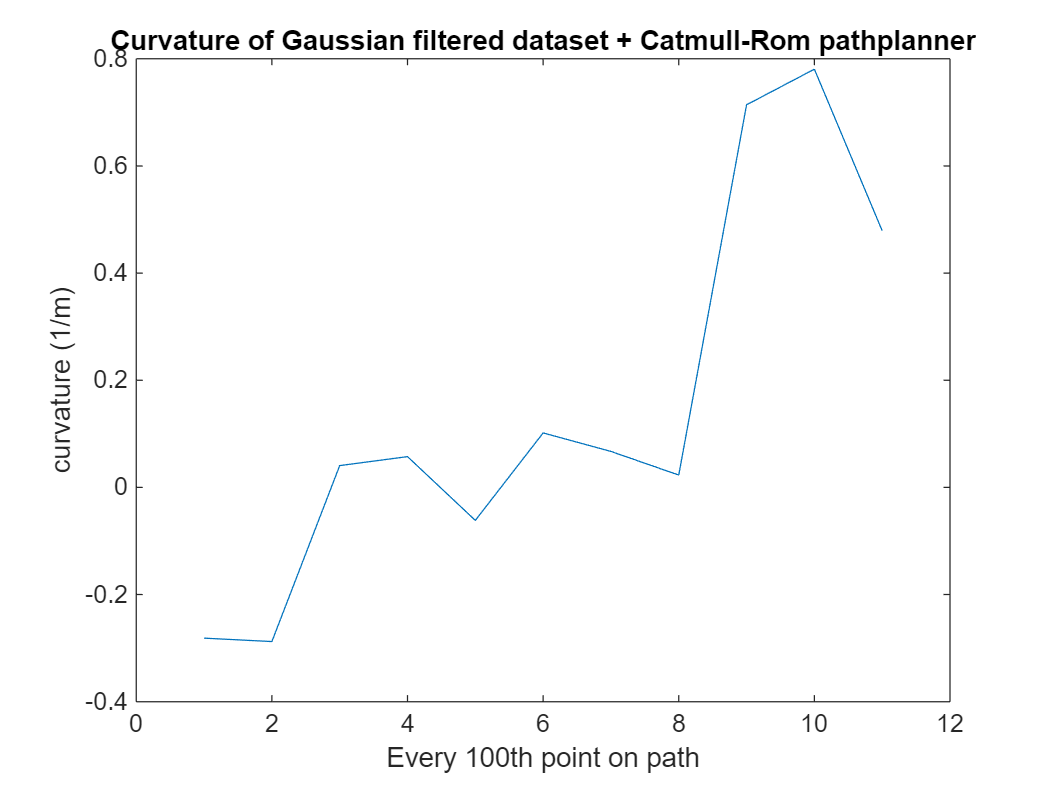


% figure;
Kappa2 = LineCurvature2D([smooth_path_x(1:100:end), smooth_path_y(1:100:end)]);
Kappa2(abs(Kappa2) > 10) = 0;
plot(Kappa2);
title('Curvature of Gaussian filtered dataset + Catmull-Rom pathplanner');
xlabel('Every 100th point on path');
ylabel('curvature (1/m)')

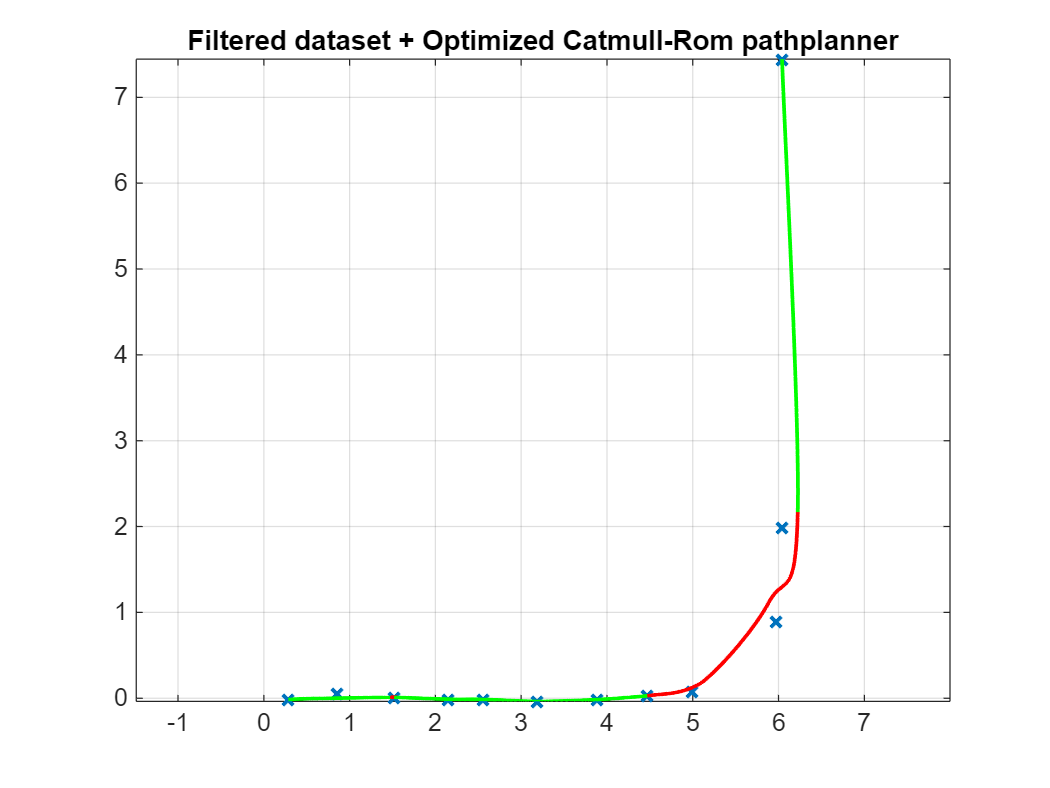

figure;
plot(coords(:,1), coords(:,2), 'x', 'LineWidth', 1.5, 'DisplayName', 'Coordinates');
title('Filtered dataset + Optimized Catmull-Rom pathplanner');
axis equal;
grid on;
hold on;
[altered_path_x, altered_path_y] = CatmullRomPathOptimized(coords);
hold off;


% figure;
% Kappa3 = LineCurvature2D([altered_path_x(1:100:end), altered_path_y(1:100:end)]);
% Kappa3(abs(Kappa3) > 10) = 0;
% plot(Kappa3);
% title('Curvature of Gaussian filtered dataset + Optimized Catmull-Rom pathplanner');
% xlabel('Every 100th point on path');
% ylabel('curvature (1/m)')

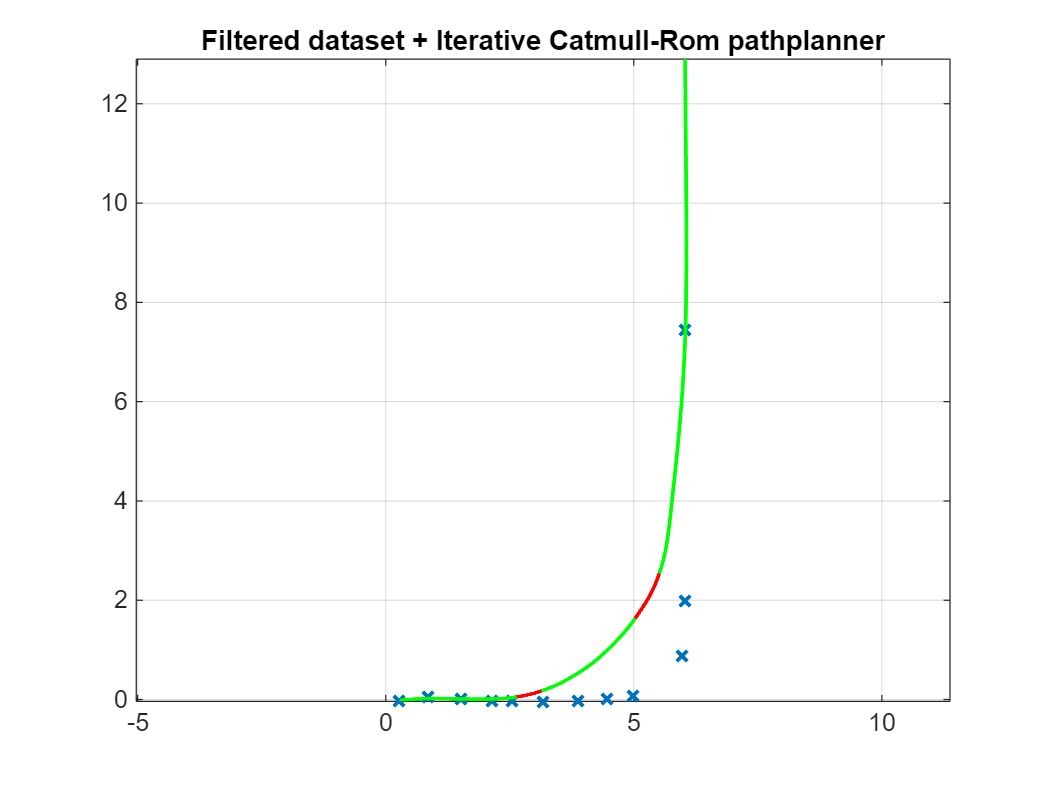

figure;
plot(coords(:,1), coords(:,2), 'x', 'LineWidth', 1.5, 'DisplayName', 'Coordinates');
title('Filtered dataset + Iterative Catmull-Rom pathplanner');
axis equal;
grid on;
hold on;
[Iterative_path_x, Iterative_path_y] = CatmullRomPathIterative(coords, 1/2.6, 50);
hold off;


% figure;
% Kappa4 = LineCurvature2D([global_path_x(1:100:end), global_path_y(1:100:end)]);
% Kappa4(abs(Kappa4) > 10) = 0;
% plot(Kappa4);
% title('Curvature of Gaussian filtered dataset + Global Catmull-Rom pathplanner');
% xlabel('Every 100th point on path');
% ylabel('curvature (1/m)')

function [path_x, path_y] = CatmullRomPath(coords)
    n_points = size(coords, 1);
    t = linspace(0, 1, 100);
    path_x = [];
    path_y = [];
    
    % Add artificial points to ensure first and last points are included
    extended_coords = [2*coords(1,:) - coords(2,:);  % Extrapolated before the first point
                       coords; 
                       2*coords(end,:) - coords(end-1,:)]; % Extrapolated after the last point

    % Iterate through all segments
    for i = 2:n_points
        P0 = extended_coords(i-1, :);
        P1 = extended_coords(i, :);
        P2 = extended_coords(i+1, :);
        P3 = extended_coords(i+2, :);
        
        % Calculate Catmull-Rom segment
        catmull_rom_segment = 0.5 * (2*P1 + (-P0 + P2) .* t' + ...
                                (2*P0 - 5*P1 + 4*P2 - P3) .* (t'.^2) + ...
                                (-P0 + 3*P1 - 3*P2 + P3) .* (t'.^3));

        % Store path coordinates
        path_x = [path_x; catmull_rom_segment(:,1)];
        path_y = [path_y; catmull_rom_segment(:,2)];
        
        K = LineCurvature2D([catmull_rom_segment(:,1), catmull_rom_segment(:,2)]);
        K(abs(K) > 10) = 0;

        if any(K > 0.385)
            plot(catmull_rom_segment(:,1), catmull_rom_segment(:,2), 'LineWidth', 1.5, Color="red");
        else
            plot(catmull_rom_segment(:,1), catmull_rom_segment(:,2), 'LineWidth', 1.5, Color="green");
        end
    end
end

function [path_x, path_y] = CatmullRomPathAltered(coords)
    i = 2;
    n_points = size(coords, 1);
    t = linspace(0, 1, 100);
    path_x = [];
    path_y = [];
    
    % Add artificial points to ensure first and last points are included
    extended_coords = [2*coords(1,:) - coords(2,:);  % Extrapolated before the first point
                       coords; 
                       2*coords(end,:) - coords(end-1,:)]; % Extrapolated after the last point

    % Iterate through all segments
    while i < n_points + 1
        if i == 2
            P0 = extended_coords(i-1, :);
            P1 = extended_coords(i, :);
            P2 = extended_coords(i+1, :);
            P3 = extended_coords(i+2, :);
        end

        % Calculate Catmull-Rom segment
        catmull_rom_segment = catmullRomSegment(P0, P1, P2, P3, t);

        K = LineCurvature2D([catmull_rom_segment(:,1), catmull_rom_segment(:,2)]);
        K(abs(K) > 10) = 0;

        if any(K > 0.385)
            max(K)
            plot(catmull_rom_segment(:,1), catmull_rom_segment(:,2), 'LineWidth', 1.5, Color="red");
            [P1, P2] = curveAdjuster(P1, P2, K);
        else
            plot(catmull_rom_segment(:,1), catmull_rom_segment(:,2), 'LineWidth', 1.5, Color="green");
            
            % Store path coordinates
            path_x = [path_x; catmull_rom_segment(:,1)];
            path_y = [path_y; catmull_rom_segment(:,2)];
            
            P0 = P1;
            P1 = P2;
            P2 = P3;
            P3 = extended_coords(i+2, :);

            i = i+1;
        end
    end
end

function [path_x, path_y] = CatmullRomPathOptimized(coords)
    i = 2;
    n_points = size(coords, 1);
    t = linspace(0, 1, 100);
    path_x = [];
    path_y = [];
    
    % Add artificial points for boundary conditions
    extended_coords = [2*coords(1,:) - coords(2,:);
                       coords; 
                       2*coords(end,:) - coords(end-1,:)];

    max_curvature = 0.385;  % Constraint

    options = optimoptions('fmincon', 'Algorithm', 'sqp', 'Display', 'off');

    while i < n_points + 2
        if i == 2
            P0 = extended_coords(i-1, :);
            P1 = extended_coords(i, :);
            P2 = extended_coords(i+1, :);
            P3 = extended_coords(i+2, :);
        end
        
        % P0 = extended_coords(i-1, :);
        % P1 = extended_coords(i, :);
        % P2 = extended_coords(i+1, :);
        % P3 = extended_coords(i+2, :);

        % Compute segment length for bounding
        segment_length = norm(P2 - P1);
        max_adjustment = 0.2 * segment_length;

        % Define bounds for P2 only (P1 is fixed)
        lb = P2 - max_adjustment;
        ub = P2 + max_adjustment;

        % Optimize P2 only
        P2_opt = fmincon(@(P) curvature_cost(P, P0, P1, P3, t, max_curvature), ...
                        P2, [], [], [], [], lb, ub, [], options);

        P2 = P2_opt;
        
        % Generate segment with optimized P1 and P2
        catmull_rom_segment = catmullRomSegment(P0, P1, P2, P3, t);

        % Compute curvature for visualization
        K = LineCurvature2D([catmull_rom_segment(:,1), catmull_rom_segment(:,2)]);
        K(abs(K) > 10) = 0;

        % Plot the optimized segment
        if any(abs(K) > max_curvature)
            plot(catmull_rom_segment(:,1), catmull_rom_segment(:,2), 'r', 'LineWidth', 1.5);
        else
            plot(catmull_rom_segment(:,1), catmull_rom_segment(:,2), 'g', 'LineWidth', 1.5);
        end

        % Store path
        path_x = [path_x; catmull_rom_segment(:,1)];
        path_y = [path_y; catmull_rom_segment(:,2)];

        % Shift to next segment
        P0 = P1;
        P1 = P2;
        P2 = P3;
        
        if i < n_points
            P3 = extended_coords(i+2, :);
        else
            P3 = P2; % Repeat P2 to avoid out-of-bounds error
        end

        i = i+1;
    end
end

function cost = curvature_cost(P2, P0, P1, P3, t, max_curvature)
    % Generate segment with optimized P2 (keeping P1 fixed)
    segment = catmullRomSegment(P0, P1, P2, P3, t);
    
    % Compute curvature
    K = LineCurvature2D([segment(:,1), segment(:,2)]);
    K(abs(K) > 10) = 0;

    % Cost: Penalize curvature values exceeding the constraint
    cost = sum(max(0, abs(K) - max_curvature).^2);
end

function [path_x, path_y] = CatmullRomPathIterative(coords, max_curvature, max_iterations)
    n_points = size(coords, 1);
    t = linspace(0, 1, 100);
    path_x = [];
    path_y = [];
    
    % Add artificial points for boundary conditions
    extended_coords = [2*coords(1,:) - coords(2,:); coords; 2*coords(end,:) - coords(end-1,:)];
    
    options = optimoptions('fmincon', 'Algorithm', 'sqp', 'Display', 'off');
    
    for iter = 1:max_iterations
        modified = false; % Track if any point was modified
        i = 2;
        
        while i < n_points + 2
            P0 = extended_coords(i-1, :);
            P1 = extended_coords(i, :);
            P2 = extended_coords(i+1, :);
            if i+2 <= size(extended_coords, 1)
                P3 = extended_coords(i+2, :);
            else
                P3 = extended_coords(end, :); % Laatste punt herhalen om out-of-bounds te vermijden
            end

            
            % Generate Catmull-Rom segment
            segment = catmullRomSegment(P0, P1, P2, P3, t);
            K = LineCurvature2D([segment(:,1), segment(:,2)]);
            
            % Check if curvature exceeds max limit
            if any(abs(K) > max_curvature)
                modified = true;
                segment_length = norm(P2 - P1);
                max_adjustment = 0.1 * segment_length;
                lb = P2 - max_adjustment;
                ub = P2 + max_adjustment;
                
                % Optimize P2
                P2_opt = fmincon(@(P) curvature_cost(P, P0, P1, P3, t, max_curvature), ...
                                P2, [], [], [], [], lb, ub, [], options);
                
                % Adaptive spreading if the change is too large
                P2 = (P2 + P2_opt) / 2;
                extended_coords(i+1, :) = P2;
            end
            
            i = i + 1;
        end
        
        % Stop iterating if no modifications were made
        if ~modified
            break;
        end
    end
    
    % Generate final path
    i = 2;
    while i < n_points + 2
        P0 = extended_coords(i-1, :);
        P1 = extended_coords(i, :);
        P2 = extended_coords(i+1, :);
        if i+2 <= size(extended_coords, 1)
            P3 = extended_coords(i+2, :);
        else
            P3 = extended_coords(end, :);
        end
        
        segment = catmullRomSegment(P0, P1, P2, P3, t);
        path_x = [path_x; segment(:,1)];
        path_y = [path_y; segment(:,2)];
        
        % Compute curvature for visualization
        K = LineCurvature2D([segment(:,1), segment(:,2)]);
        K(abs(K) > 10) = 0;

        % Plot the optimized segment
        if any(abs(K) > max_curvature)
            plot(segment(:,1), segment(:,2), 'r', 'LineWidth', 1.5);
        else
            plot(segment(:,1), segment(:,2), 'g', 'LineWidth', 1.5);
        end

        i = i + 1;
    end
end

function segment = catmullRomSegment(P0, P1, P2, P3, t)
    segment = 0.5 * (2*P1 + (-P0 + P2) .* t' + (2*P0 - 5*P1 + 4*P2 - P3) .* (t'.^2) + (-P0 + 3*P1 - 3*P2 + P3) .* (t'.^3));
end

function resampled_coords = ResamplePath(coords, d_spacing)
    % Resample path to have approximately equal spacing between points
    % Inputs:
    %   - coords: Nx2 array of waypoints
    %   - d_spacing: Desired spacing between points
    % Output:
    %   - resampled_coords: New set of waypoints with uniform spacing

    % Compute cumulative distance along the original path
    distances = [0; cumsum(sqrt(sum(diff(coords).^2, 2)))];  
    total_length = distances(end);

    % Determine number of points based on desired spacing
    num_points = round(total_length / d_spacing);

    % Generate new interpolated distances
    new_distances = linspace(0, total_length, num_points);

    % Interpolate new x and y coordinates
    resampled_x = interp1(distances, coords(:,1), new_distances, 'linear');
    resampled_y = interp1(distances, coords(:,2), new_distances, 'linear');

    % Combine into output array
    resampled_coords = [resampled_x', resampled_y'];
end

function filtered_coords = preprocessCoords(coords, threshold)
    % Reduce noise by clustering close points and selecting representative ones
    filtered_coords = coords(1, :); % Initialize with the first point
    
    for i = 2:size(coords, 1)
        % Calculate the distance to the last filtered point
        dist = norm(coords(i, :) - filtered_coords(end, :));
        
        if dist > threshold
            filtered_coords = [filtered_coords; coords(i, :)]; % Add point if far enough
        end
    end
end

function filtered_coords = clusterAverageCoords(coords, threshold)
    % Initialize filtered coordinates with the first point
    filtered_coords = coords(1, :);
    temp_cluster = coords(1, :); % Temporary cluster for averaging

    for i = 2:size(coords, 1)
        % Compute distance to last stored point
        dist = norm(coords(i, :) - filtered_coords(end, :));

        if dist < threshold
            % Add to temporary cluster (points within threshold)
            temp_cluster = [temp_cluster; coords(i, :)];
        else
            % Compute cluster centroid (average)
            filtered_coords(end, :) = mean(temp_cluster, 1);
            
            % Start a new cluster
            temp_cluster = coords(i, :);
            filtered_coords = [filtered_coords; coords(i, :)];
        end
    end

    % Ensure last cluster is averaged
    filtered_coords(end, :) = mean(temp_cluster, 1);
end